# Attitude Controller Analysis

Created: Jérémie X. J. Bannwarth, 2017/09/28

## Summary

This document describes the PX4 attitude controller. The code run during a single iteration of the operation of the controller is presented and annotated.

The controller is composed of two main components: an attitude loop and a rate loop.

The attitude loop consists of a simple proportional (P) gain applied on the angular error. However, the angle error computation is slightly involved due to the use of quatrenions. The first half of this document aims to demistify this computation.

The rate loop consists of a straightforward proportional integral derivative (PID) controller and is described in the second half of this document.

## Controller inputs and constants

Inputs:

addpath( 'libquat' )
thrust_sp = 0.5;
q_sp  = EulerToQuat( deg2rad( [25, -10, 20] ) );
q_att = EulerToQuat( deg2rad( [0, 0, 0] ) );
R_sp  = QuatToRot( q_sp );
R     = QuatToRot( q_att );
roll_rate = 0;
pitch_rate = 0;
yaw_rate = 0;

Constants:

att_p = [6.5; 6.5; 2.8];
rates_p = [0.15; 0.15; 0.2];
rates_i = [0.05; 0.05; 0.1];
rates_d = [0.003; 0.003; 0];
rate_ff = [0; 0; 0];
dt = 0.002;

Initialize:

rates_int = 0;
rates_prev = 0;

## Roll and pitch error

The rotation matrices (also referred to as direction cosine matrices, or DCM) $\mathbf{R}_z$ and $\mathbf{R}_{\mathrm{sp}_z}$ are used to represent the current and desired orientation of the UAV respectively. Such matrices can be thought of as a reference frame defined by three orthogonal normalized vectors in $\mathcal{\mathbb{R}}^3$;$\mathbf{R}_x$, $\mathbf{R}_y$, and $\mathbf{R}_z$. Expressed in matrix form,


$$\mathbf{R} = \pmatrix{ \mathbf{R}_x & \mathbf{R}_y & \mathbf{R}_z } = 
\pmatrix{x_1 & y_1 & z_1 \cr
x_2 & y_2 & z_2 \cr
x_3 & y_3 & z_3}.$$


Using this representation, we can visualise the current and desired orientation graphically, as shown in Fig. 1. Note that the PX4 attitude controller operates in a north-east-down (NED) reference frame.

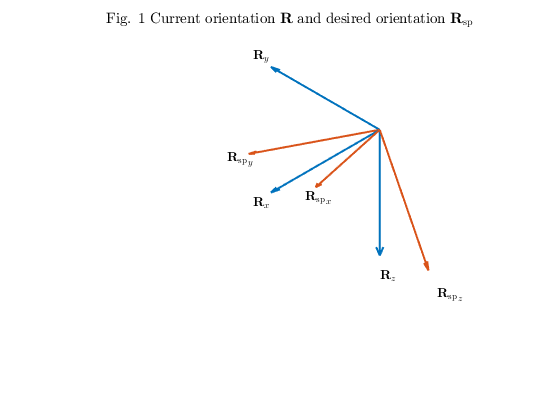

figure('Name', 'Rotation matrices');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title( 'Fig. 1 Current orientation $\mathbf{R}$ and desired orientation $\mathbf{R}_\mathrm{sp}$', 'interpreter', 'latex' )
cmap = get(gca,'colororder');
h(1:3) = PlotReferenceFrame( R,    1, '\mathbf{R}',      cmap(1,:) );
h(4:6) = PlotReferenceFrame( R_sp, 1, '\mathbf{R}_\mathrm{sp}', cmap(2,:) );
xlim auto; ylim auto; zlim auto
view([1 1 1])
set(findobj(gcf, 'type', 'axes'), 'Visible', 'off') % Clean up graph

set(findall(gca, 'type', 'text'), 'Visible', 'on');

The approach taken by the PX4 attitude controller's attitude loop is to separate the error computation in two: first roll and pitch, and then yaw. Aligning $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ can be done purely using roll and pitch, so it is done first.

% Try to move thrust vector shortest way, because yaw response is slower than roll/pitch
R_z = R(:,3);
R_sp_z = R_sp(:,3);

Fig. 2 shows $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ graphically.

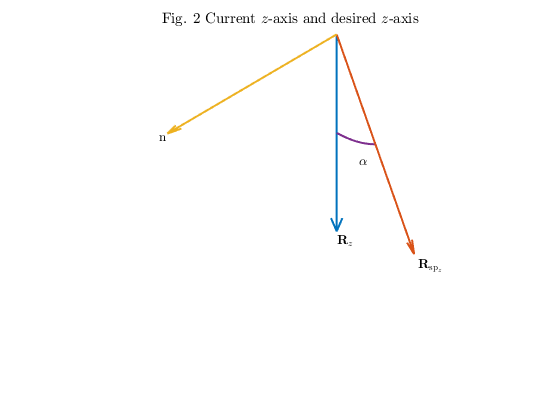

figure('Name', 'Z axes');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title( 'Fig. 2 Current $z$-axis and desired $z$-axis', 'interpreter', 'latex' )
cmap = get(gca,'colororder');
PlotVector( R_z, 1, '$\mathbf{R}_z$', cmap(1,:), '' )
PlotVector( R_sp_z, 1, '$\mathbf{R}_{\mathrm{sp}_z}$', cmap(2,:), '' )
PlotVector( cross(R_z, R_sp_z)./norm(cross(R_z, R_sp_z)), 1, 'n', cmap(3,:), '' )
PlotArc( R, R_sp_z, 0.5, '$\alpha$', cmap(4,:) )
view([1 1 1])
set(findobj(gcf, 'type','axes'), 'Visible', 'off') % Clean up graph

set(findall(gca, 'type', 'text'), 'Visible', 'on');

We want to rotate from $\mathbf{R}_z$ to $\mathbf{R}_{ \mathrm{sp}_z }$ in the shortest path. The orientation of the UAV after aligning $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ without changing the UAV's yaw, can be represented as a rotation matrix $\mathbf{R}_\text{rp}$ (where $_\text{rp}$ stands for 'roll pitch'). The rotation required to align $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$ can also be described in axis angle form as the error $\alpha$ around the unit-length vector $\mathbf{n}$ which is normal to $\mathbf{R}_z$ and $\mathbf{R}_{ \mathrm{sp}_z }$, as shown in Fig. 2. Note: $\mathbf{n}$ and $\mathbf{e}_R$ are expressed with respect to the current body frame of reference, which explains the presence of the $\mathbf{R}$ matrix in the cross-product equation.

Since $|\mathbf{R}| = |\mathbf{R}_{\mathrm{sp}_z}| = 1$, we can use the properties of the cross and dot products to find $\alpha$ and $\mathbf{n}$:


$$\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}_z| |\mathbf{R}_{\mathrm{sp}_z}| (\mathbf{R}\mathbf{n}) \, {\sin\alpha} \rightarrow \sin\alpha = \left|\mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z}\right|, \;$$



$$\mathbf{n} = \mathbf{R}^\top \frac{1}{\sin\alpha} \left( \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} \right)\,,$$



$$\mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z} = |\mathbf{R}|\cos\alpha \rightarrow \cos\alpha = \mathbf{R} \cdot \mathbf{R}_{\mathrm{sp}_z}\,,$$



$$\alpha= \arctan\left( \frac{ | \mathbf{R}_z \times \mathbf{R}_{\mathrm{sp}_z} | }{  \mathbf{R}_z \cdot \mathbf{R}_{\mathrm{sp}_z}} \right)\,.$$


$\alpha$ and $\mathbf{n}$ can be combined as a single vector $\mathbf{e}_R$, which we will refer to as our 'error' vector:


$$\mathbf{e}_R = \alpha \mathbf{n}.$$


The PX4 implementation is shown below.

% Axis and sin(angle) of desired rotation
e_R = R' * cross(R_z, R_sp_z);             % sin alpha * n

% Calculate angle error
e_R_z_sin = norm(e_R);                     % sin alpha
e_R_z_cos = dot(R_z, R_sp_z);              % cos alpha

% Calculate rotation matrix after roll/pitch only rotation
if ( e_R_z_sin > 0.0 )
    e_R_z_angle = atan2(e_R_z_sin, e_R_z_cos); % alpha
    e_R_z_axis = e_R ./ e_R_z_sin;             % n
    
    e_R = e_R_z_axis .* e_R_z_angle;           % e_R

The cross product between two vectors $\mathbf{a}$ and $\mathbf{b}$ can also be expressed as a matrix multiplication:


$$\mathbf{a} \times \mathbf{b} = \mathbf{A} \mathbf{b}, \; \mathrm{where} \; \mathbf{A} =
\pmatrix{0 & -a_3 & a_2 \cr
a_3 & 0 & -a_1 \cr
-a_2 & a_1 & 0}.$$


$\mathbf{R}_\mathrm{rp}$ can be thus obtained by the following equation:


$$\mathbf{R}_\text{rp} = \mathbf{R} \left(
\mathbf{I}
+
\mathbf{E}_R \sin\alpha
+
{\mathbf{E}_R}^2 \left( 1 - \cos\alpha\right)
\right)$$


where $\mathbf{E}_R$ is the cross-product matrix form of $\mathbf{e}_R$. Full derivation for this equation can be found at:

S. van Der Walt, *The 3 x 3 rotation matrix. *Available: [http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf](http://dip.sun.ac.za/~stefan/TWB264/notas/engels/12_rot_3x3_eng.pdf).

These equations are implemented in the PX4 firmware as shown below.

    % Cross product matrix for e_R_axis
    e_R_cp = zeros(3,3); % E_R
    e_R_cp(1, 2) = -e_R_z_axis(3);
    e_R_cp(1, 3) =  e_R_z_axis(2);
    e_R_cp(2, 1) =  e_R_z_axis(3);
    e_R_cp(2, 3) = -e_R_z_axis(1);
    e_R_cp(3, 1) = -e_R_z_axis(2);
    e_R_cp(3, 2) =  e_R_z_axis(1);
    
    % Rotation matrix for roll/pitch only rotation
    R_rp = R * ( eye(3,3) + e_R_cp * e_R_z_sin + e_R_cp * e_R_cp * (1.0 - e_R_z_cos) );
else
    % Zero roll/pitch rotation
    R_rp = R;
end

We now have a temporary 'error' vector, $\mathbf{e}_R$, which is still missing its yaw elements:

e_R

e_R =     0.4678
   -0.0035
         0


## Yaw error

The $z$-axes of the $\mathbf{R}_\mathrm{rp}$ and $\mathbf{R}_\mathrm{sp}$ matrices are identical, as expected.

disp(R_rp(:,3))

   -0.0033
   -0.4510
    0.8925



disp(R_sp(:,3)) 

   -0.0033
   -0.4510
    0.8925



It is possible to reach the orientation defined by $\mathbf{R}_\mathrm{sp}$ by starting at $\mathbf{R}_\mathrm{rp}$ and performing a rotation around the $z$-axis until both $x$-axes are aligned. This action only requires the use of the UAV's yaw control.

The attitude controller computes the yaw error as


$$e_{R_z} =
\arctan
\left(
\frac{ \left( \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} \right)
\cdot \mathbf{R}_{\mathrm{sp}_z}
}{ 
\mathbf{R}_{\mathrm{rp}_x} \cdot \mathbf{R}_{\mathrm{sp}_x} } \right) w_\psi\,.$$


where $w_\psi$ is a weight used by the attitude controller to prioritize the roll/pitch control when the UAV pose is far from the horizontal. It is defined as


$$w_\psi = {R_{\mathrm{sp}_{3,3}}}^2.$$


This is implemented as shown below.

% Calculate weight for yaw control
yaw_w = R_sp(3, 3) * R_sp(3, 3); % w_psi
% R_rp and R_sp has the same Z axis, calculate yaw error
R_sp_x = R_sp(:, 1);
R_rp_x = R_rp(:, 1);
e_R(3) = atan2( dot( cross(R_rp_x, R_sp_x), R_sp_z), dot(R_rp_x, R_sp_x) ) * yaw_w;

Fig. 3 shows a graphical representation of the equation for $e_{R_z}}$.

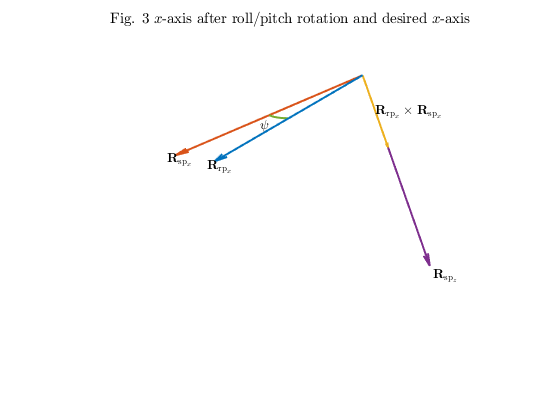

figure('Name', 'Yaw control');
axes( 'dataaspectratio', [1 1 1], 'projection', 'orthographic' )
title( 'Fig. 3 $x$-axis after roll/pitch rotation and desired $x$-axis', 'interpreter', 'latex' )
cmap = get(gca,'colororder');
PlotVector( R_rp_x, 1, '$\mathbf{R}_{\mathrm{rp}_x}$', cmap(1,:), '' )
PlotVector( R_sp_x, 1, '$\mathbf{R}_{\mathrm{sp}_x}$', cmap(2,:), '' )
PlotVector( R_sp_z, 1, '$\mathbf{R}_{\mathrm{sp}_z}$', cmap(4,:), '' )
PlotVector( cross(R_rp_x, R_sp_x), 1, '$\mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x}$', cmap(3,:), 'side' )
PlotArc( R_sp, R_rp_x, 0.5, '$\psi$', cmap(5,:), 1 )
view([1 1 1])
set(findobj(gcf, 'type','axes'), 'Visible', 'off') % Clean up graph

set(findall(gca, 'type', 'text'), 'Visible', 'on');

Since the $z$-axes of  $\mathbf{R}_\mathrm{rp}$ and $\mathbf{R}_\mathrm{sp}$ are aligned, $\mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x}$ and  $\mathbf{R}_{\mathrm{sp}_z}$ are coincident. Therefore,  $\left( \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} \right) \cdot \mathbf{R}_{\mathrm{sp}_z} = | \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} |$ if $| \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} | \leq |\mathbf{R}_{\mathrm{sp}_z}|$, which is true in all cases since $| \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} | = | \mathbf{R}_{\mathrm{rp}_x} | | \mathbf{R}_{\mathrm{sp}_x} | \sin \psi$, where $\psi$ is the yaw angle of the robot, $|\mathbf{R}_{\mathrm{rp}_x}| = |\mathbf{R}_{\mathrm{sp}_x}| = 1$, and $\max( \sin \psi) = 1$. This means that the equation used to find $e_{R_z}$ in the attitude controller is equivalent to


$$e_{R_z} =
\arctan
\left(
\frac{ | \mathbf{R}_{\mathrm{rp}_x} \times \mathbf{R}_{\mathrm{sp}_x} |
}{ 
\mathbf{R}_{\mathrm{rp}_x} \cdot \mathbf{R}_{\mathrm{sp}_x} } \right) w_\psi = \psi w_\psi\,.$$


Coming back to the weighting factor $w_\psi = {R_{\mathrm{sp}_{3,3}}}^2$, ${R_{\mathrm{sp}_{3,3}}}$ corresponds to the bottom right element of the $\mathbf{R}_\mathrm{sp}$ matrix. This element is the component of $\mathbf{R}_{\mathrm{sp}_z}$ along the world frame's $z$-axis. $R_{\mathrm{sp}_{3,3}} = 1$ when the UAV is hovering perfectly level. $R_{\mathrm{sp}_{3,3}} = 0$ when the UAV is tilted at 90 degrees (any combination of roll and pitch resulting in $\mathbf{R}_{\mathrm{sp}_z} \cdot \pmatrix{ 0 & 0 & 1 }^\top = 0$). Fig. 4 shows how the error is weighted for varying tilt angles, where 'tilt angle' refers to the angle between $\pmatrix{ 0 & 0 & 1 }^\top$ and $\mathbf{R}_{\mathrm{sp}_z}$. It can be seen that at a tilt angle of 20 degrees, the yaw 'error' used by the controller will only be 88% of what it is when the UAV is perfectly level.

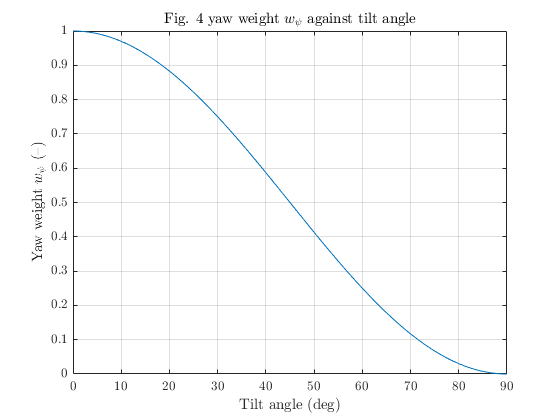

figure('Name', 'Yaw control'); grid on; box on; hold on;
tilt = linspace(0, pi/2, 100);
plot( rad2deg(tilt), cos(tilt).^2 )
title( 'Fig. 4 yaw weight $w_\psi$ against tilt angle', 'interpreter', 'latex' )
xlabel( 'Tilt angle (deg)', 'interpreter', 'latex' )
ylabel( 'Yaw weight $w_\psi$ (--)', 'interpreter', 'latex' )
set( gca, 'TickLabelInterpreter', 'latex' )

The attitude controller has a special way to handle large rotations, which would not normally be used when station keeping.

if ( e_R_z_cos < 0.0 )
    % For large thrust vector rotations use another rotation method:
    % calculate angle and axis for R -> R_sp rotation directly
    q_error = RotToQuat( R' * R_sp );
    
    if ( q_error(1) >= 0.0 )
        e_R_d =  q_error(2:end) * 2.0;
    else
        e_R_d = -q_error(2:end) * 2.0;
    end
    
    
    % Use fusion of Z axis based rotation and direct rotation
    direct_w = e_R_z_cos * e_R_z_cos * yaw_w;
    e_R = e_R * (1.0 - direct_w) + e_R_d * direct_w;
end

We now have the final 'error' vector, $\mathbf{e}_R$.

e_R

e_R =     0.4678
   -0.0035
    0.3090


## Attitude control law

Finally, a simple proportional control law is applied to reduce the error to 0:


$$\dot{\phi}_\mathrm{sp} = P_\phi e_{R_x}\,,$$



$$\dot{\theta}_\mathrm{sp} = P_\theta e_{R_y}\,,$$



$$\dot{\psi}_\mathrm{sp} = P_\psi e_{R_z}\,,$$


where $\phi$, $\theta$, and $\psi$ represent the UAV's roll, pitch, and yaw respectively. This control law can also be expressed in vector form as


$$\nu_\mathrm{sp} = \mathbf{P} \circ \mathbf{e}_R$$


where $\circ$ is the element wise multiplication symbol, $\nu_\mathrm{sp} = \pmatrix{ \dot{\phi}_\mathrm{sp} & \dot{\theta}_\mathrm{sp} & \dot{\psi}_\mathrm{sp} }^\top$, and $\mathbf{P} = \pmatrix{ P_\phi & P_\theta & P_\psi }^\top$.

% Calculate angular rates setpoint
rates_sp = att_p .* e_R;

The controller applies some saturation to the rates, which are not an issue in the cases we are looking at.

% Limit rates
% for i = 1:3
%     if ( (flag_control_velocity_enabled || flag_control_auto_enabled) && ...
%          ~flag_control_manual_enabled)
%         rates_sp(i) = constrain(rates_sp(i), -auto_rate_max(i), auto_rate_max(i));
%     else
%         rates_sp(i) = constrain(rates_sp(i), -mc_rate_max(i), mc_rate_max(i));
%     end
% end

We thus have the final desired rates.

rad2deg(rates_sp)

ans =   174.2339
   -1.2919
   49.5680


## Attitude rates

The code for calculating the attitude rates has a few saturations and optional features which are not included in this section, as they do not have a significant effect on the output.

First, we compute the rate error, $\mathbf{e}_\nu$, which is defined as


$$\mathbf{e}_\nu = \nu_\mathrm{sp} - \nu.$$


This is implemented in the PX4 controller in a simple fashion.

% Current body angular rates
rates = [roll_rate; pitch_rate; yaw_rate];

% Angular rates error
rates_err = rates_sp - rates;

The output of the rate controller is a vector of roll, pitch, and yaw control commands, defined as $\mathbf{c}$. These commands are constrained in the range $[ -1, 1 ]$, and are later combined with the thrust command and converted to normalised motor PWM signals by the PX4 motor mixer. As a consequence, they do not directly correspond to a physical quantity.

The rate controller is a simple discrete-time PID controller. The code supports feedforward action from rate setpoint to control command but the gain is set to 0 by default. Assuming no integral saturation occurs, the output of the controller at time $T$ is given by


$$\mathbf{c}_T = \mathbf{P}_\nu \circ \mathbf{e}_{\nu_T} + \mathbf{D}_\nu \circ \frac{1}{\Delta T} \left( \nu_{T-1} - \nu_T \right) +  \mathbf{I}_\nu \circ \sum^{T}_{t=\Delta T} \mathbf{e}_{\nu_t} \Delta T$$


where $\mathbf{P}_\nu$, $\mathbf{D}_\nu$, and $\mathbf{I}_\nu$ are vectors of proportional, integral, and derivative gains respectively. $\Delta T$ is the size of the timestep. In the original PX4 implementation this time step is variable, but it was found to be consistently close to 0.002 s, which corresponds to a rate of 500 Hz. As a consequence, the MATLAB implementation of the code uses a fixed rate of 500 Hz.

% Perform the integration using a first order method and do not propaate the result if out of range or invalid
rates_int = rates_int + rates_i .* rates_err * dt;

att_control = rates_p .* rates_err + rates_int + rates_d .* (rates_prev - rates) ./ dt + rate_ff .* rates_sp; % c

rates_sp_prev = rates_sp;
rates_prev = rates;

We thus have the final controller output, as shown below.

att_control

att_control =     0.4564
   -0.0034
    0.1732
